# Python interop

## Setup Python

websave("get-pip.py","https://bootstrap.pypa.io/get-pip.py");
!python get-pip.py

Defaulting to user installation because normal site-packages is not writeable
  Using cached pip-25.0.1-py3-none-any.whl.metadata (3.7 kB)
Using cached pip-25.0.1-py3-none-any.whl (1.8 MB)
  Attempting uninstall: pip
    Found existing installation: pip 25.0.1
    Uninstalling pip-25.0.1:
      Successfully uninstalled pip-25.0.1
□  WARNING: The scripts pip, pip3 and pip3.10 are installed in '/home/matlab/.local/bin' which is not on PATH.
  Consider adding this directory to PATH or, if you prefer to suppress this warning, use --no-warn-script-location.□□
□Successfully installed pip-25.0.1


!python -m pip --version

pip 25.0.1 from /home/matlab/.local/lib/python3.10/site-packages/pip (python 3.10)


## Connect to Python

!which python

/usr/bin/python


!python --version

Python 3.10.16


pyenv(Version="/usr/bin/python")

ans =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "/usr/bin/python"
          Library: "libpython3.10.so.1.0"
             Home: "/usr"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


## Call Python from MATLAB

### Via a live task

% Python code input
pycode = [...
"import math",...
"res = math.sqrt(42)",...
"print(res)"...
];

try
    [res] = pyrun(pycode, ...
         [ "res" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

6.48074069840786


res = 6.4807


% Clear temporary variables from workspace and from Python
clear pycode;
res^2

ans = 42

### Via the py. prefix

py.math.sqrt(42)

ans = 6.4807

## Call Python packages

### Astropy

!python -m pip install astropy

Defaulting to user installation because normal site-packages is not writeable


% Import the Astropy Time module
astropy_time = py.importlib.import_module('astropy.time');

% Create a Time object from a string
time_str = '2023-10-01T12:00:00';
time_obj = astropy_time.Time(time_str)

time_obj =   Python Time with properties:

                T: [1x1 py.astropy.time.core.Time]
            cache: [1x1 py.collections.defaultdict]
    delta_ut1_utc: [1x1 py.numpy.ndarray]
           format: [1x4 py.str]
        in_subfmt: [1x1 py.str]
             info: [1x1 py.astropy.time.core.TimeInfo]
         isscalar: 1
              jd1: 2460219
              jd2: 0
         location: [1x1 py.NoneType]
             mask: [1x1 py.numpy.ndarray]
           masked: 0
             ndim: [1x1 py.int]
       out_subfmt: [1x1 py.str]
        precision: [1x1 py.int]
            scale: [1x3 py.str]
            shape: [1x0 py.tuple]
             size: [1x1 py.int]
         unmasked: [1x1 py.astropy.time.core.Time]
            value: [1x23 py.str]
        writeable: 1
           SCALES: [1x7 py.tuple]

    2023-10-01T12:00:00.000


time_obj.to_datetime

ans = datetime
   01-Oct-2023 12:00:00


### Obspy

!python -m pip install obspy

Defaulting to user installation because normal site-packages is not writeable
Collecti

% Python code input
pycode2 = [...
"from obspy import UTCDateTime",...
"from obspy.clients.fdsn import Client",...
"",...
"# Initialize the FDSN client to connect to IRIS",...
"client = Client(""IRIS"")",...
"",...
"# Define the time period for the data (one minute of data)",...
"starttime = UTCDateTime(""2020-01-01T00:00:00"")",...
"endtime = starttime + 60  # 60 seconds later",...
"",...
"# Retrieve the waveform data",...
"st = client.get_waveforms(network=""IU"", station=""ANMO"", location=""00"", channel=""BHZ"",",...
"                          starttime=starttime, endtime=endtime)",...
"",...
"data = st.traces[0].data",...
"stats = dict(st.traces[0].stats)"...
];

try
    [data, stats] = pyrun(pycode2, ...
         [ "data" "stats" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode2;
    rethrow(ME)
end

data =   Python ndarray:

   1779   1790   1790   1792   1804   1800   1794   1803   1813   1806   1803   1808   1806   1805   1800   1791   1797   1793   1778   1782   1780   1773   1768   1757   1755   1752   1735   1733   1736   1723   1720   1718   1709   1704   1698   1693   1686   1681   1673   1667   1666   1652   1651   1649   1637   1638   1628   1621   1621   1609   1609   1610   1597   1594   1598   1588   1580   1583   1581   1581   1577   1570   1579   1574   1566   1573   1570   1568   1572   1571   1576   1580   1584   1585   1593   1603   1600   1606   1613   1610   1612   1624   1625   1621   1633   1640   1645   1652   1658   1662   1668   1673   1669   1686   1690   1687   1704   1705   1717   1723   1722   1738   1736   1741   1753   1747   1753   1758   1752   1754   1760   1760   1757   1761   1761   1760   1764   1760   1758   1764   1760   1751   1754   1750   1755   1756   1741   1745  

stats =   Python dict with no properties.

    {'sampling_rate': 40.0, 'delta': 0.025, 'starttime': UTCDateTime(2020, 1, 1, 0, 0, 0, 19538), 'endtime': UTCDateTime(2020, 1, 1, 0, 0, 59, 994538), 'npts': 2400, 'calib': 1.0, 'network': 'IU', 'station': 'ANMO', 'location': '00', 'channel': 'BHZ', 'mseed': AttribDict({'dataquality': 'M', 'number_of_records': 5, 'encoding': 'STEIM2', 'byteorder': '>', 'record_length': 512, 'filesize': 2560}), '_format': 'MSEED', '_fdsnws_dataselect_url': 'http://service.iris.edu/fdsnws/dataselect/1/query', 'processing': ['ObsPy 1.4.1: trim(endtime=UTCDateTime(2020, 1, 1, 0, 0, 59, 994538)::fill_value=None::nearest_sample=True::pad=False::starttime=UTCDateTime(2019, 12, 31, 23, 59, 59, 994538))']}



% Clear temporary variables from workspace and from Python
clear pycode2;
% Output the stream object st directly to manipulate it in MATLAB
% st.traces{1}.stats
data = int32(data)

data = 1x2400 int32 row vector
   1779   1790   1790   1792   1804   1800   1794   1803   1813   1806   1803   1808   1806   1805   1800   1791   1797   1793   1778   1782   1780   1773   1768   1757   1755   1752   1735   1733   1736   1723   1720   1718   1709   1704   1698   1693   1686   1681   1673   1667   1666   1652   1651   1649   1637   1638   1628   1621   1621   1609


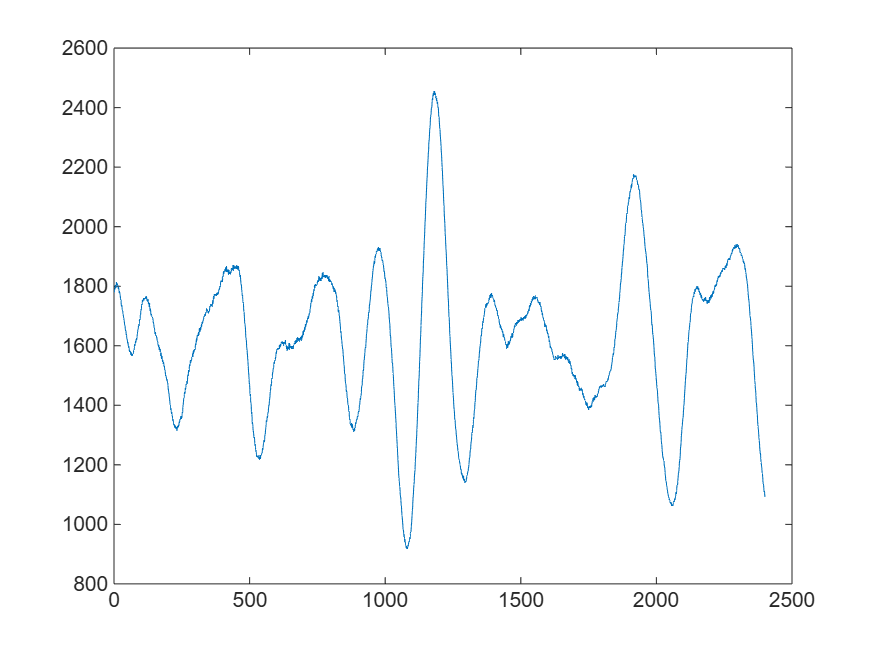

plot(data)